# Modelagem Motor em Laplace

## Boas Praticas


clear all;
close all;
clc; 


## Sis de 1º ordem


$$G_1(s) = \frac{4}{s+4}$$


Num = 4;        
Den = [1 4];

G1 = tf(Num,Den)

G1 =
 
    4
  -----
  s + 4
 
Continuous-time transfer function.



G1*G1

ans =
 
        16
  --------------
  s^2 + 8 s + 16
 
Continuous-time transfer function.



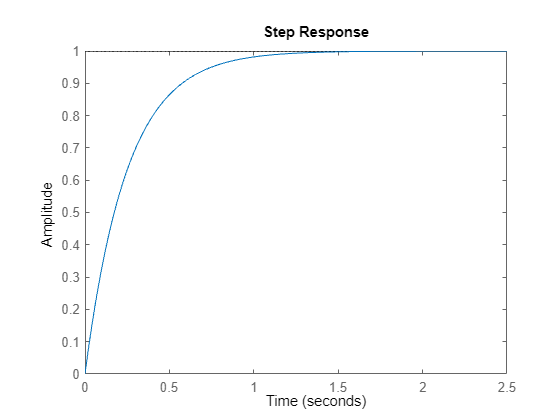



%%% Anti tranf

step(G1)

%%% Verifica a estabilidade 
roots(Den)   

ans = -4

## Sis de 2º ordem


$$G_2 = \frac{4}{s^2+4}$$


Den2 = [1 0 4];
G2 = tf(Num,Den2)

G2 =
 
     4
  -------
  s^2 + 4
 
Continuous-time transfer function.



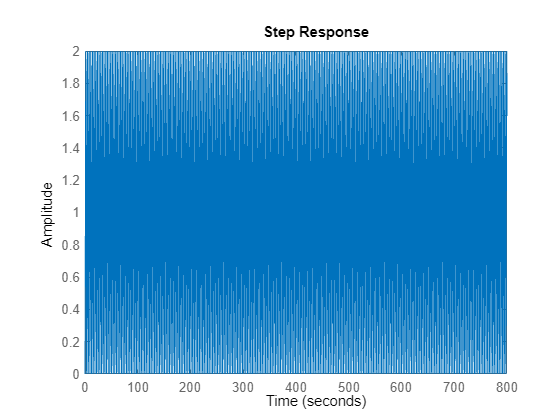

step(G2)

roots(Den2)

ans =    0.0000 + 2.0000i
   0.0000 - 2.0000i


Den3 = [1 2 4]

Den3 =      1     2     4


G3 = tf(Num,Den3)

G3 =
 
        4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.



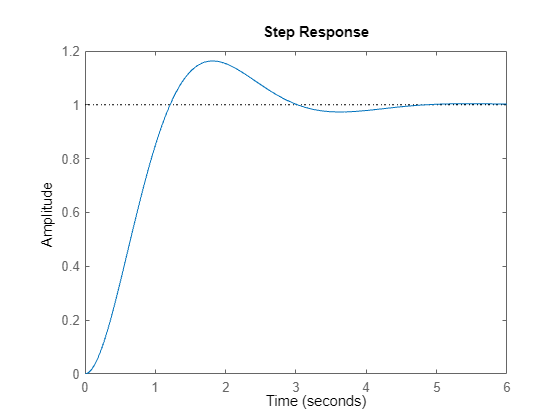

step(G3)

roots(Den3)

ans =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i



Den4 = [1 -2 4]

Den4 =      1    -2     4


G4 = tf(Num,Den4)

G4 =
 
        4
  -------------
  s^2 - 2 s + 4
 
Continuous-time transfer function.



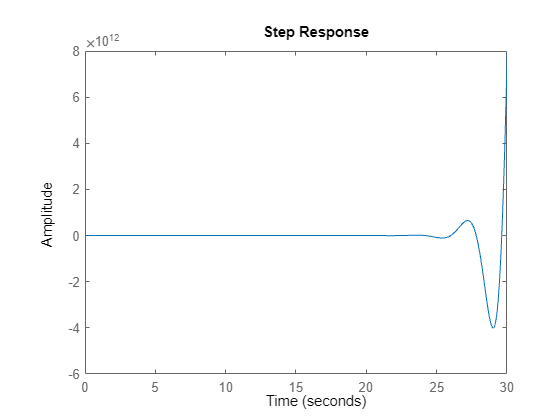

step(G4)

roots(Den4)

ans =    1.0000 + 1.7321i
   1.0000 - 1.7321i



Den5 = [1 8 4]

Den5 =      1     8     4


G5 = tf(Num,Den5)

G5 =
 
        4
  -------------
  s^2 + 8 s + 4
 
Continuous-time transfer function.



step(G5); hold;

Current plot held


roots(Den5)

ans =    -7.4641
   -0.5359


N = 0.5;
D = [1 0.5];
G6 = tf(N,D)

G6 =
 
    0.5
  -------
  s + 0.5
 
Continuous-time transfer function.



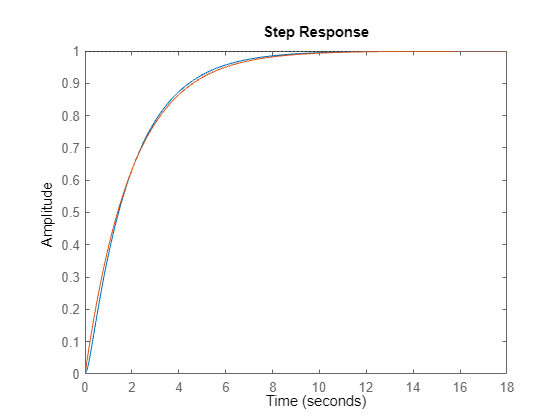

Current plot released


step(G6); hold;


$$G_3 = \frac{4}{s^2+2s+4}
$$



$$G_4= \frac{4}{s^2-2s+4}$$



$$G_5 = \frac{4}{s^2+8s+4}$$


## Importando um modelo real

%%% Usando função gerada pelo Matlab

[Velociadade,Posicao,Entrada] = DataMotor('exp7.txt', 1);

## Estimando um modelo matemático

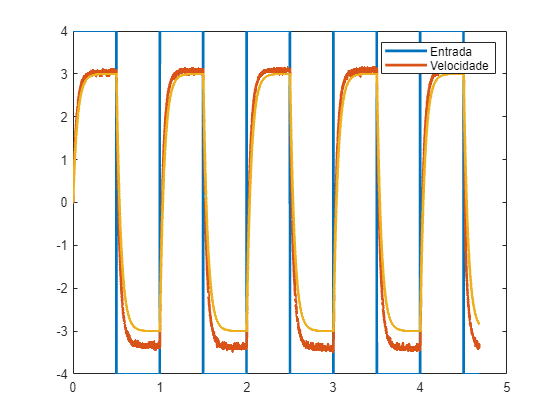

%%% Criando o vetor tempo 

Tamostragem = 1e-3;                                     %tx de amostragem 
Npontos     = length(Velociadade);                      % Num de pontos 
tempo       = [0:Tamostragem:(Npontos-1)*Tamostragem];  % Vetor tempo 

%%% Modelo de Laplace

K = 0.75;  %%% Ganho do modelo 
T = 0.05;  %%% Const de tempo 

Gmod = tf(K,[T 1]); %%% Modelo em Laplce 

Vmod = lsim(Gmod,Entrada,tempo);
 
plot(tempo,Entrada,tempo,Velociadade,tempo,Vmod,'LineWidth',2); legend("Entrada","Velocidade");